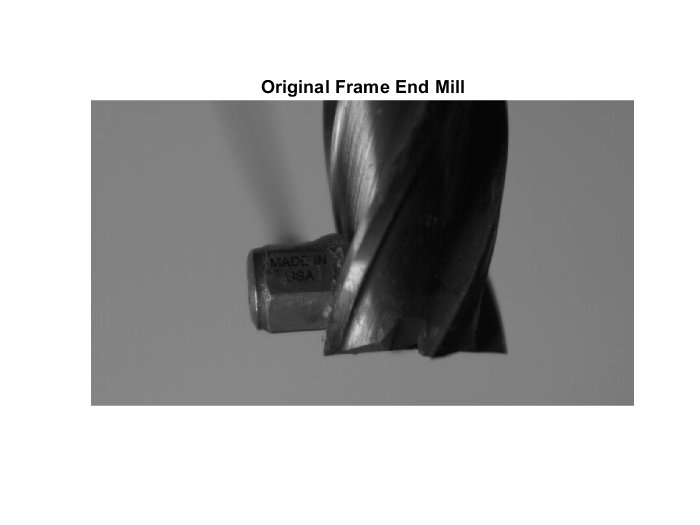

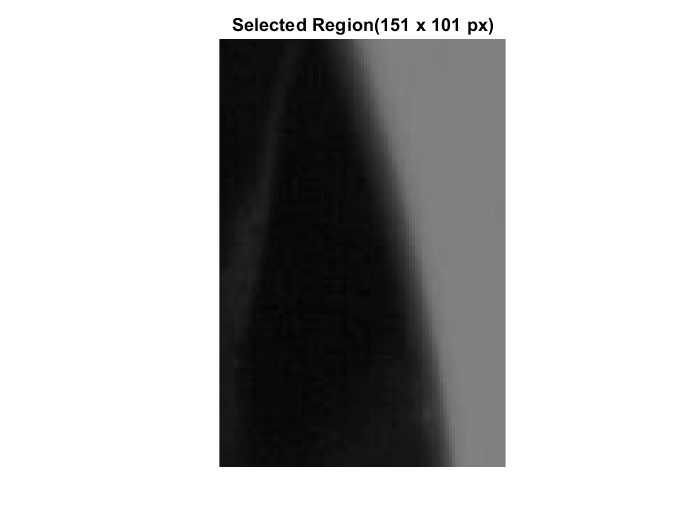

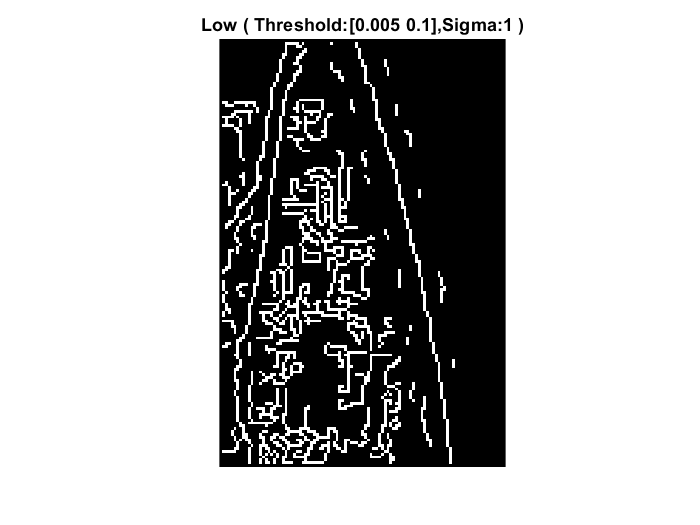

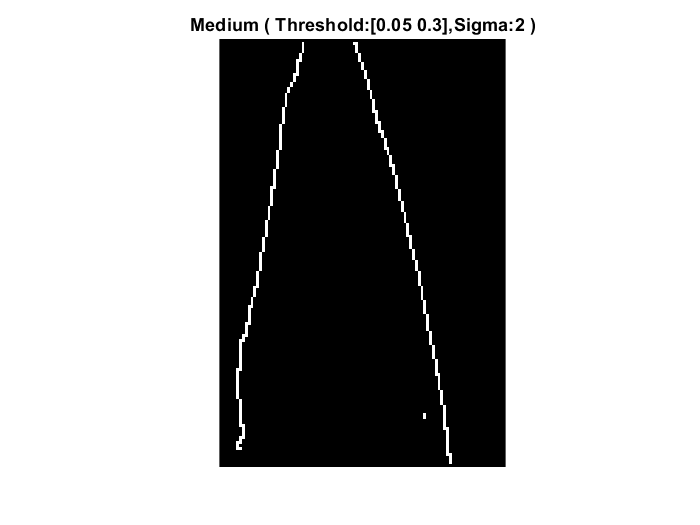

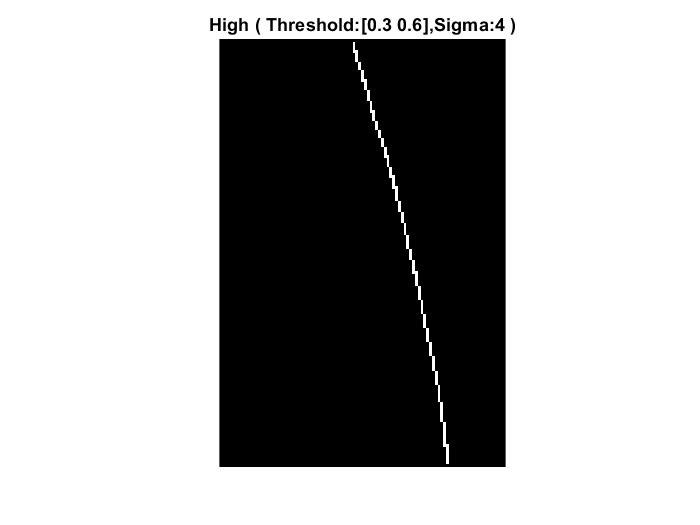

clear;
v=VideoReader("C:\Users\Varun\Desktop\Lab\Videos\EndMill-zoomed-SR.mp4"); % Reading Video
disp1=[];
disp2=[];
disp3=[];
i=1;
x=0;
y=0;
for nFrames = 12:v.NumFrames     
    % Acquire single frame
    frameRGB = read(v,nFrames);
    I2 = rgb2gray(imcrop(frameRGB,[900 440 100 150]));
    imshow(I2)
    frameRGB1=edge(I2,'canny',[0.005 0.1],1); % Threshold 1
    [y,x]=find(frameRGB1);
    x1=mean(x)*36e-03;
    y1=mean(y)*36e-03;
    disp1(i)=x1;
    
    frameRGB2=edge(I2,'canny',[0.05 0.3],2); % Threshold 2
    [y,x]=find(frameRGB2);
    x2=mean(x)*36e-03;
    y2=mean(y)*36e-03;
    disp2(i)=x2;
    
    frameRGB3=edge(I2,'canny',[0.3 0.6],4); % Threshold 3
    [y,x]=find(frameRGB3);
    x3=mean(x)*36e-03;
    y3=mean(y)*36e-03;
    disp3(i)=x3;
    
    if nFrames==12
      % Displaying Region Selection and detected edge 
      imshow(frameRGB,'InitialMagnification','fit')
      title('Original Frame End Mill')
      figure,imshow(I2,'InitialMagnification','fit')
      title('Selected Region(151 x 101 px)')
      figure,imshow(frameRGB1,'InitialMagnification','fit')
      title('Low ( Threshold:[0.005 0.1],Sigma:1 )')
      figure,imshow(frameRGB2,'InitialMagnification','fit')
      title('Medium ( Threshold:[0.05 0.3],Sigma:2 )')
      figure,imshow(frameRGB3,'InitialMagnification','fit')
      title('High ( Threshold:[0.3 0.6],Sigma:4 )')
    end
    
    i=i+1;
end

disp1=disp1-disp1(1);% Removing Offset
disp2=disp2-disp2(1);
disp3=disp3-disp3(1);
time=(0:207)./2142;

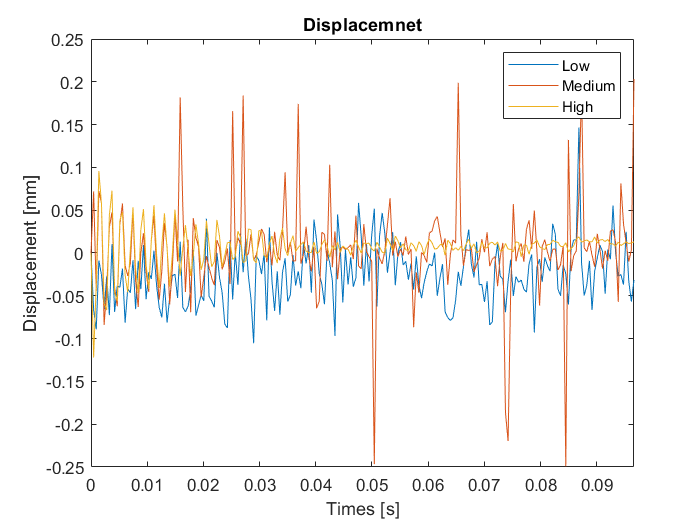

plot(time,disp1)
hold on
plot(time,disp2)
plot(time,disp3)
title('Displacemnet')
legend('Low','Medium','High')
xlabel('Times [s]')
ylabel('Displacement [mm]')
xlim([0 time(end)])
% ylim([-0.12 0.12])
hold off

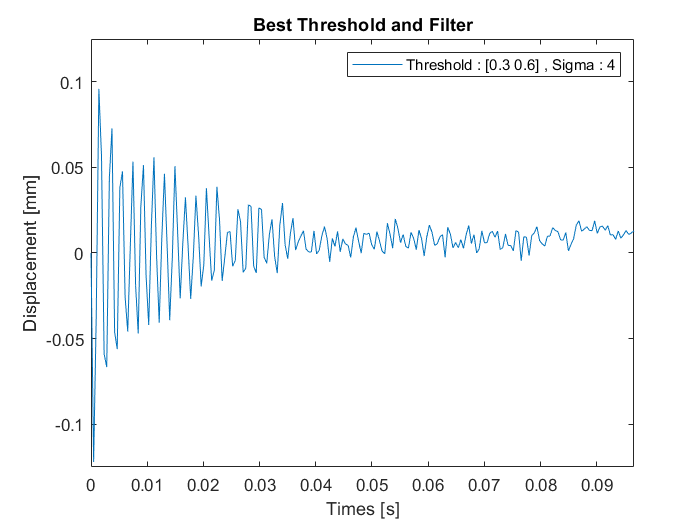

plot(time,disp3)
title('Best Threshold and Filter')
legend('Threshold : [0.3 0.6] , Sigma : 4')
xlabel('Times [s]')
ylabel('Displacement [mm]')
xlim([0 time(end)])
ylim([-0.125 0.125])

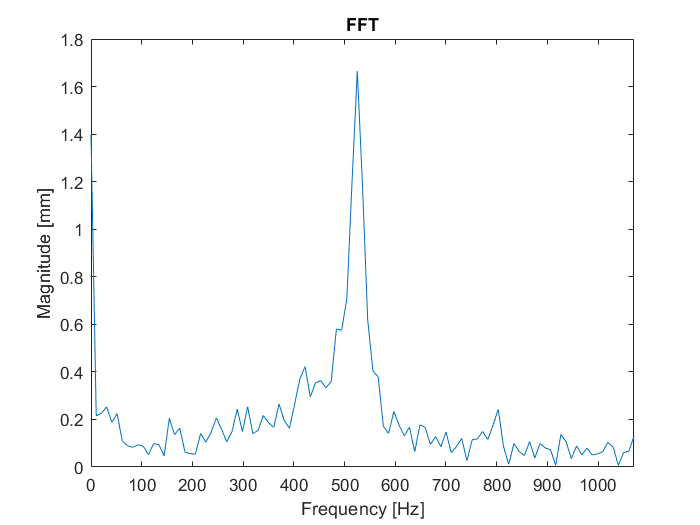

% Lenght of signal
L = length(time);
% Sampling Freq
dt = time(2) - time(1);
Fs = 1/dt;
% Define a freq. vector
f = Fs/2*linspace(0,1,(L/2+1)); % in Hz
w = (f*2*pi)'; % in rad/sec
F=fft(disp3,L); %FFT
F=F(1:length(F)/2+1);
plot(f,abs(F))
title('FFT')
xlabel('Frequency [Hz]')
ylabel('Magnitude [mm]')
xlim([0 f(end)])

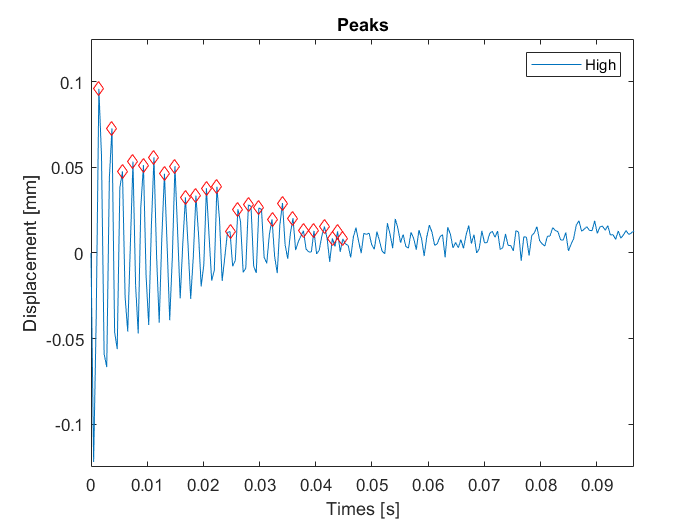

[ypk,xpk] = findpeaks(disp3(1:100));
plot(time,disp3,time(xpk),ypk,'dr');
title('Peaks')
legend('High')
xlabel('Times [s]')
ylabel('Displacement [mm]')
xlim([0 time(end)])
ylim([-0.125 0.125])

np=numel(xpk);

tn = time(xpk);    
% Calculating Logarithmic Decrement
Log_Dec = zeros(length(np));  
for i = 1:np-1 
    Log_Dec(i)= log(ypk(i)/ypk(i+1));  
end  
lambda = mean(Log_Dec); %Calculating Average Logarithmic Decrement

z1=lambda/sqrt(lambda^2 + 4*pi^2) % Zeta

z1 = 0.0163